# Matchcode Maker

The wordlebot works by finding the guess that eliminates the most of the remaining options.  To do this, it needs to know the match code for every combination of 5-letter words in wordle. This creates a 14885x14885 array of matchcodes that the Wordlebot will use to pick words.

The matchcode is the green, yellow, and grey colorings on a guess that tell you how well the guess matches the solution.

For example. Here is a game of Wordle that demonstrates four matchcodes:

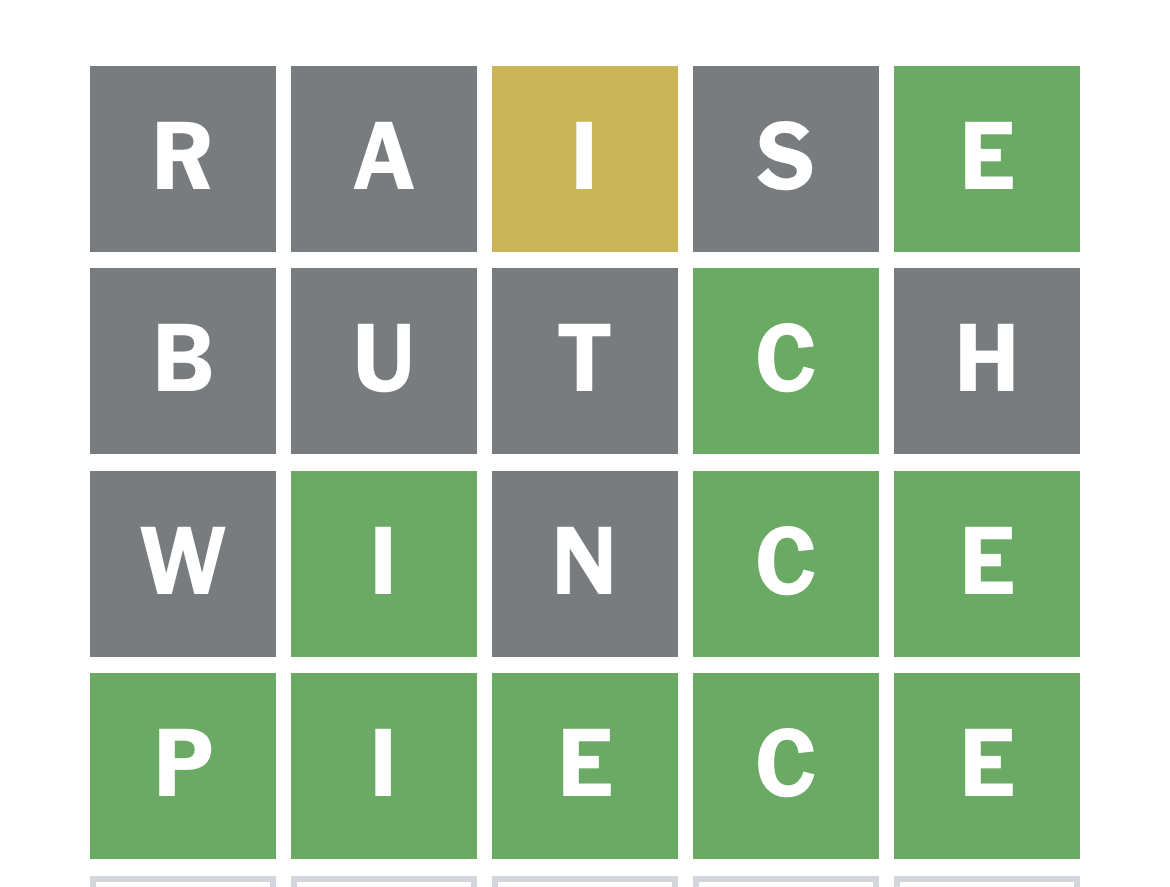

The solution here is `PIECE.` Each guess has a *matchcode* that describes the greens, yellows, and greys that appear when you make that guess for that solution.  Notice that the matchcode's don't change depending on the state of the game. They are static relationships that we can calculate beforehand and use to find the best guess word. 

In this program, we'll create a 14,885 x 14,885 array that contains the matchcodes every combination of guesses and solutions.

## Encoding the matches

When we make a guess, Wordle assigns a green, yellow, or grey background to each letter in the guess. We know how the codes work, but let's formalize it:

### Extra letters

Sometimes the player guesses a word with two of the same letter.  For example consider this game:

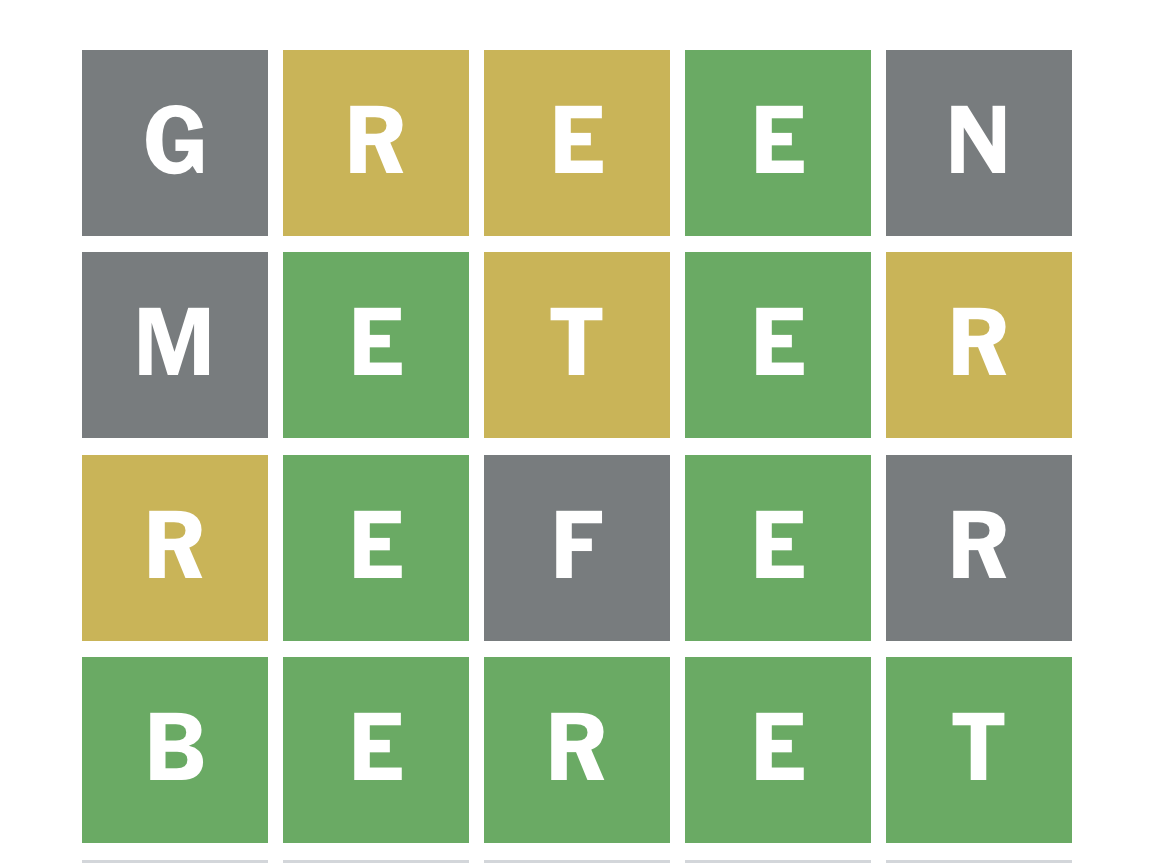

The `GREEN` guess demonstrates how Wordle handles extra letters.  There are two `Es.` One of the E's is the right letter in the right location, so it gets the green code.   The other `E` is in the word somewhere, but is not in the third spot.

The second guess shows two letters both in the correct spot. 

The third guess has two `Rs.` The first `R` is yellow because there is an `R` in the solution, but not in the first spot.  The second `R` is gray because there is only one `R` in the solution, and the leading `R` "used up" the credit for an `R`.  So when we create match codes we must only give credit to the first instance of a letter in the guess.

### Base-3 Encoding

Each letter in the match code has one of three states.  This means we can store the value for each letter as a digit in a base-3 number. Using the columns in the word as the base-three positions We can encode each letter like this:

Here is the encoding for the `GREEN``guess above:

The match code for GREEN above is 27 + 9 + 6 = 42

We will store decimal numbers that represent the matchcodes for every combination of guess and solution and then we can use them to find the best guess for any Wordle situation.

We are going to store the matchcodes with the guesses in columns and all the matchcodes for that guess in the rows.  When the guess matches the solution the matchCode is 242.

- .

## The input data

The input data is a text file of five letter words.  We read the words into a table with one variable. The table contains a vector of cell arrays. We convert the vector into an array of characters five columns wide.

The length of the array depends on the file we read.

tmptable = readtable('words4.txt','ReadVariableNames',false);
wordList = char(tmptable.Var1); % The list of legal wordle words
numWords = size(wordList,1);

### Keeping things clear

It's important to remember that there are two primary matrices in this algorithm.   Given a list of words `N` rows long, we create two matrices:

- `wordList-`This is an Nx5 array of characters, where each row contains the characters in a five-letter word.

- `greenCodes`, `yellowCodes`, and `matchCodes–`These are NxN arrays where each cell is a (guess, solution) matrix cell.

Generally, we'll pull solutions out of the `wordList`, compare them to all the guesses in `wordList`` to create a column of matchcodes for that solution.

#### Example: `words4.txt`

`words4.txt` contains 4 words.  When we read them in we get a 4x5 matrix of characters.

`wordList`

`matchCodes `will be a 4x4 array that shows how every soltuion (in the columns) affects every guess (in the rows).  The row and column numbers match the rows in `wordList`.

## Calculate the matchcodes for each solution

We'll calculate the matchcodes solution by solution by looping through `WordList `and taking each word out.  Then we do four steps:

- Create a logical array where the green matches are set to 1.

- Create a logical array where the yellow matches are set to 1.

- Add the two arrays and calculate the weigthed score for each position.

- Sum the weighted scores and store them in the `matchCode` array.

### Loop through the solutions

We loop through the wordList and choose each word as a solution.  

tic
for solNum = 1:numWords %loop through the words
    solution = wordList(solNum,:);  % Choose the next word word as the solution


### Get the exact matches for this solution

Create a logical array of `exactMatches` that will be green squares for all guesses.

    greenMatches = solution == wordList; % create a logical array of exact matches

Elapsed time is 0.004719 seconds.


### Get the letter matches for this solution

Now we have to find the spots in all the guesses where there would be a yellow square.  This is a trickier matching problem for three reasons:

- We have to match the letters in the solution against all the guesses.

- We have to remove the cases where the guesses have an exact match as these have already been counted.

- We have to remove extra letters in a guess so that we don't get extra yellow squares in the matchCode.

If there are mulitple copies of the same letter in a guess, they get coded this way:

- Any exact matches get green codes.

- If there are additional letters, then we put yellow codes on the guess letters from left to right until all the matching letters in the solution are used up.

In the example above, the GREEN guess got a green code on the `E` that matched the second `E` in `BERET`.  The other `E` in the guess got marked yellow. In the `METER` guess, both `E` letters got a green code.  If there had been a third `E` it would have been grey.  

In the `REFER` guess, the first `R` got a yellow code because there is one `R` in `BERET`.  The second `R` is grey.

### Get a list of letters.

We get a list of unique letters from the solution.  Now we'll search for these letters in all the guesses.  We're going to fill the `yellowMatches` logical array with `1's` wherever there is a yellow letter. Since we have no matches yet, we initialize `yellowMatches` to be all false. Notice that it is the same size as `wordList`. 

    solutionLetters = unique(solution); % get the letters
    yellowMatches = false(size(wordList)); % initialize yellowMatches


matchCodes =    242     0     0    80
     0   242    63     0
     0   135   242     0
    80     0     0   242


### Finding matches and guesses with extra letters.

Now we'll loop through each letter in the solution and find all the words that contain that letter.  

    for letterNum = 1:numel(solutionLetters) % loop through each letter
        letter = solutionLetters(letterNum); % Get the next letter
        letterMatches = (wordList == letter); % Find all the letter matches

### Find the guesses with extra letters

`letterMatches` contains a `1` in every spot where there is a letter in `wordList` that matches the letter we're checking.  For example, if we are looking at `o` in the list below, `letterMatches` looks like this table. Notice that the guesses `pooch` and `oozle` have extra `o` letter relative to tango. Looking at `o` the 

searching for `o` we get this:

We count the number of matching letters by summing `letterMatches` along the columns to get `guessLetterCounts`:

We are working on the solution `tango` so the `solutionLetterCount` is 1.

        guessLetterCounts = sum(letterMatches,2);
        solutionLetterCount = count(solution, letter);


Now we can find extra letters for every guess by subtracting the number of letters in the solution from the number in the guesses. We don't want negative numbers in cases where the letter is not in that postiion, so we use the `max() `function to set negative numbers to 0.

Sutracting 1 (the number of `o` in `tango` from guessLetterCounts gives use `extraLetters`:

        extraLetters = max(guessLetterCounts - solutionLetterCount,0);

Two rows have extra letters.  We get these row numbers using `find() to fill extraLetterRows:`

        extraLetterRows = find(extraLetters > 0);

We're going to be removing `1`s from the letter matches, but we don't want to remove matches from green squares since we know those are not extra.  We take the green square matches out of `letterMatches` to create `letterMatchOnly:`

        letterMatchOnly = max(letterMatches - greenMatches,0); % remove the exact matches


### Removing the extra matches

`extraLetterRows` contains the row that have extra letters.  We loop only through those rows and put the row number in `guessRow. `

        for elgRow = 1:numel(extraLetterRows)
            guessRow = extraLetterRows(elgRow);


Now we get the columns from `letterMatchOnly` that contain `1s`. 

Starting at the last column (using flip()`) we set `1s` to `0s` and decrement the extra letter counter for that row until it reaches zero. 

            matchCols = find(letterMatchOnly(guessRow,:));
            matchCols = flip(matchCols);
            for mc = 1:numel(matchCols)
                letterMatchOnly(guessRow,matchCols(mc)) = 0;
                extraLetters(guessRow) = extraLetters(guessRow) - 1;
                if extraLetters(guessRow) == 0
                    break
                end
            end
        end


We build `yellowMatches` solution-by-solution and letter-by-letter.

        yellowMatches = yellowMatches | letterMatchOnly;
    end

We get 2 points for a green match, and 1 point for a yellow match.  This never adds to 3 since greens and yellows do not overlap.

Then we multiply the points by the base-3 column mulitpliers and store the resulting array of match codes in `matchCodes` for the solution we are working on.

    totalPoints = greenMatches .* 2 + yellowMatches;
    scoreArray =  totalPoints .* [3^4 3^3 3^2 3^1 3^0]; % aka 3 .^(4:-1:0)
    matchCodes(:,solNum) = sum(scoreArray,2);
end
toc
if height(matchCodes) < 10
    matchCodes
end

We go back to the top of the loop and treat the next word as the solution.